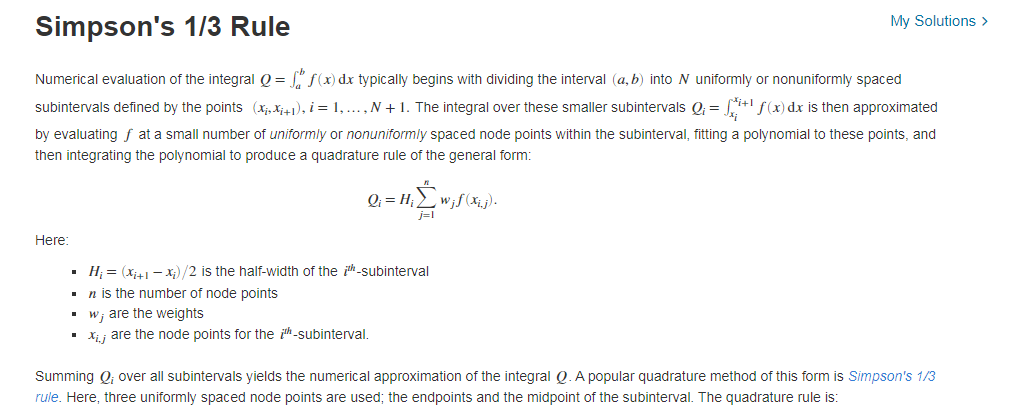

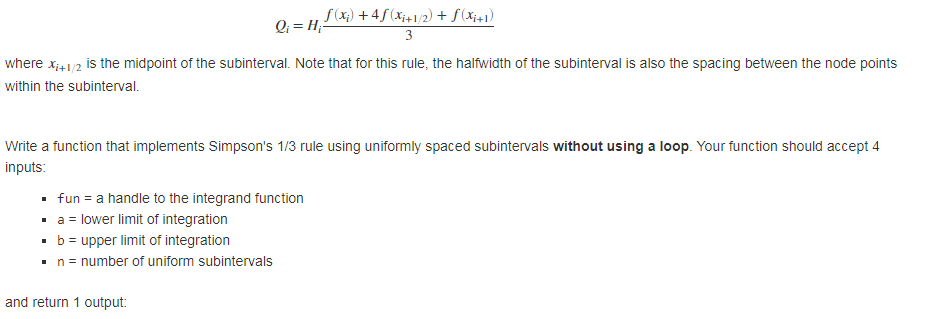

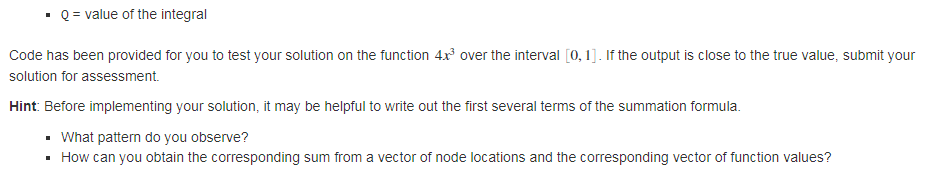

fun = @(x) 4*x.^3;
a = 0; b = 1; n = 11;
Q = quadSimp(fun,a,b,n)

Q =    1.000000000000000


function Q = quadSimp(fun,a,b,n)

    % Obtain the node locations.
    int=(b-a)/(n+1);
    x=a:int:(b-int);
    h=int/2;
    % Evaluate the function at the nodes.
    fx=fun(x);
    f1x=fun(x+int);
    fmx=fun((x+int+x)/2);
    % Evaluate the integral by summing according to the formula given in the problem description.
    Q =sum(h.*(fx+4.*fmx+f1x)./3);
end
